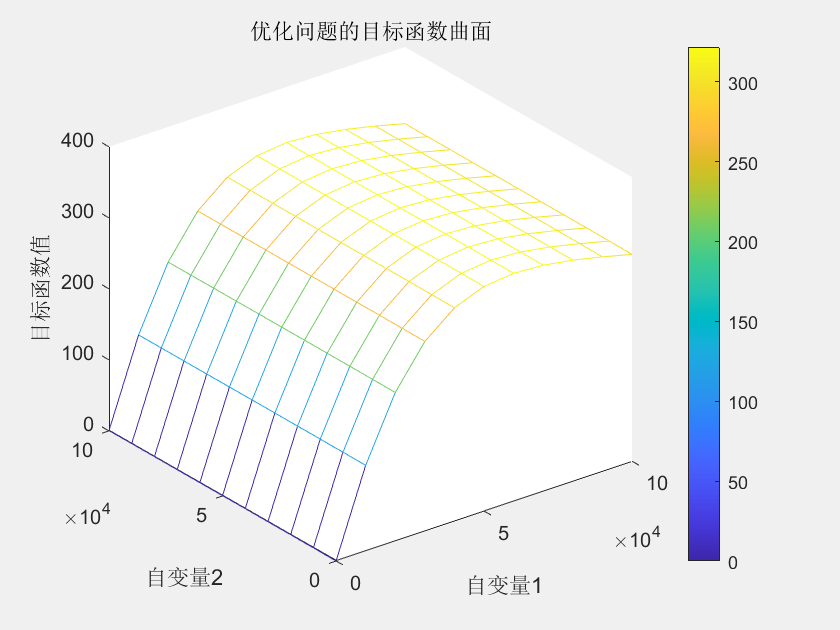

clc,clear  

% 定义参数范围和步长
x1_range = 0:10000:100000;  % 自变量1的范围：0到100000
x2_range = 0:10000:100000;  % 自变量2的范围：0到1

% 计算目标函数值
[X1, X2] = meshgrid(x1_range, x2_range);
Z = zeros(size(X1));
for i = 1:numel(X1)
    Z(i) = -Obj_fun([X1(i), X2(i)]);
end
% 绘制三维曲面
mesh(X1, X2, Z);
colormap("parula");
colorbar;
% 启用交互式旋转
rotate3d on;
% 添加标题和轴标签
title('优化问题的目标函数曲面');
xlabel('自变量1');
ylabel('自变量2');
zlabel('目标函数值');

## Main

narvs = 2;
x_lb = [0,0];
%x_ub = 1; % x的上界
x_ub= [100000,100000];
%options = optimoptions('particleswarm','HybridFcn',@fmincon);
options = optimoptions('particleswarm','MaxIterations',800,'PlotFcn','pswplotbestf','Display','iter')   

options =   particleswarm 选项:

   设置属性:
                   Display: 'iter'
             MaxIterations: 800
                   PlotFcn: 'pswplotbestf'

   默认属性:
               CreationFcn: @pswcreationuniform
         FunctionTolerance: 1.0000e-06
                 HybridFcn: []
              InertiaRange: [0.1000 1.1000]
        InitialSwarmMatrix: []
          InitialSwarmSpan: 2000
        MaxStallIterations: 20
              MaxStallTime: Inf
                   MaxTime: Inf
      MinNeighborsFraction: 0.2500
            ObjectiveLimit: -Inf
                 OutputFcn: []
      SelfAdjustmentWeight: 1.4900
    SocialAdjustmentWeight: 1.4900
                 SwarmSize: 'min(100,10*numberofvariables)'
               UseParallel: 0
             UseVectorized: 0



                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20          -317.1          -275.4        0
    1              40          -321.4          -308.7        0
    2              60          -321.6            -302        0
    3              80          -321.7          -281.6        0
    4             100          -321.7          -259.9        1
    5             120          -321.7          -298.3        2
    6             140          -321.7          -306.4        3
    7             160          -321.7          -284.7        0
    8             180          -321.7            -255        1
    9             200          -321.7          -254.8        2
   10             220          -321.7          -301.7        3
   11             240          -321.7          -291.2        4
   12             260          -321.7          -305.3        5
   13             280          -321.7          -

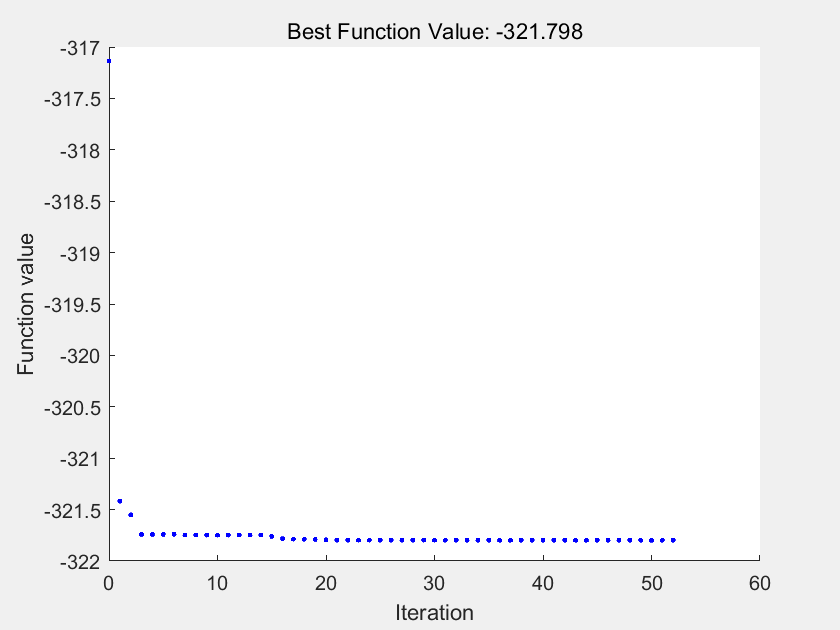

x = 1.0e+04 *

    6.0543    9.9900


fval = -321.7978

exitflag = 1

output = 包含以下字段的 struct :
      rngstate: [1×1 struct]
    iterations: 52
     funccount: 1060
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []


[x,fval,exitflag,output] = particleswarm(@Obj_fun, narvs, x_lb, x_ub,options) 

fprintf('最大平均功率为%f',fval)

最大平均功率为-321.797819

function W=Obj_fun(c)
%initialize parameter
    g=9.8;                                   %重力加速度 (m/s2)
    %l0=0.5;                                 %弹簧原长 (m)       
    %T_end=40*T;                             %总数值模拟时间(s) 
    T_end=200;                               %总数值模拟时间(s)  
    %%初值设置               
    v1=0;                                    %浮子的初始速度 (m/s)
    v2=0;                                    %振子的初始速度 (m/s)
    x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
    x_v=0;                                   %振子的初始位移 (m)
    theta1=0;
    theta2=0;
    omega1=0;
    omega2=0;
    X0=[x_f;x_v;v1;v2;theta1;theta2;omega1;omega2];
    tspan=[0,T_end];
    options = odeset('MaxStep', 0.01);  % 设置最大步长为 0.2
    [t, X] = ode45(@(t,X)S_diff_equ(t,X,c), tspan, X0, options);
    X=X';
    l=length(t);
    delta_v=abs(X(3,:)-X(4,:));
    W1=trapz(t(l-floor(l/10):end),c(1)*delta_v(l-floor(l/10):end).^2)/(t(end)-t(l-floor(l/10)));
    W1=-W1;
    delta_omega=X(7,:)-X(8,:);
    W2=trapz(t(l-floor(l/10):end),c(2)*delta_omega(l-floor(l/10):end).^2)/(t(end)-t(l-floor(l/10)));
    W2=-W2;
    W=W1+W2;
end
function dxdt=S_diff_equ(t,X,k)
    k1=k(1);
    k2=k(2);
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    h_v=0.5;                                 %振子高度
    r_v=0.5;                                 %振子底半径
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1091.099;                          %垂荡附加质量 (kg)
    J_add=7142.493;                          %纵摇附加转动惯量 (kg·m2)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke1=80000;                               %直线弹簧刚度 (N/m)
    ke2=250000;                              %旋转弹簧刚度
    w=1.9806;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr1=528.5018;                            %垂荡兴波阻尼系数 (N·s/m)
    kr2=1655.909;                            %纵摇兴波阻尼系数 (N·m·s)
    f_max=1760;                              %垂荡激励力振幅 (N)
    M_max=2140;                              %纵摇激励力矩振幅 (N·m)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;        %水面的高度(m)
    l0=0.5-m2*g/ke1;                         %弹簧初始长度
    k_f=8890.7;                              %静水恢复力矩系数
    J1=8422.3;
    J2=m2*(h_v^2/12+r_v^2/4)+m2*(h_v/2+l0+X(4))^2;
    dxdt=zeros(8,1);
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k1*(X(3)-X(4))-ke1*(X(1)-X(2))+f_max*cos(w*t)-kr1*X(3)-rho*g*pi*r_cost^2*X(1))/(m1+m_add);
    dxdt(4)=(k1*(X(3)-X(4))+ke1*(X(1)-X(2)))/m2;
    dxdt(5)=X(7);
    dxdt(6)=X(8);
    dxdt(7)=(-k2*(X(7)-X(8))-ke2*(X(5)-X(6))+M_max*cos(w*t)-kr2*X(7)-k_f*X(5))/(J1+J_add);
    dxdt(8)=(k2*(X(7)-X(8))+ke2*(X(5)-X(6)))/J2;
end